# **Fall 2017 MATLAB Assignment D: PROGRAMS**

## Math 151-230, Team PineappleDreamTeam, #4 Marwan Elzarka, Haley Hefner, Parker Kallman, Stewart Landes, 

# *Gilat 5th Edition, Chapter 6*

## *Page 212, Problem 10*

Description

nyc = [33,33,18,29,40,55,19,22,32,37,58,54,51,52,45,41,45,39,36,45,36,18,19,19,28,34,44,21,23,30,39];
denver=[39,48,61,39,14,37,43,38,46,39,55,46,46,39,54,45,52,52,62,45,62,40,25,57,60,57,20,32,50,48,28];
% Part A
avg1 = sum(nyc)/length(nyc);
avg2 = sum(denver)/length(denver);
fprintf('The averages for NYC and Denver are %.0f and  %.0f degrees.',avg1,avg2);

The averages for NYC and Denver are 35 and  44 degrees.

% Part B
high1 = [];
high2=[];
for i=1:length(nyc)
    if nyc(i)>avg1
        high1 = [high1 nyc(i)];
    end
end
for i = 2:length(denver)
        if denver(i)>avg2
        high2 = [high2 denver(i)];
        end
end
fprintf(' NYC had %.0f days greater than average and Denver had %.0f days greater than average.',length(high1),length(high2));

 NYC had 16 days greater than average and Denver had 18 days greater than average.

% Part C
days = 0;
for i=1:length(nyc)
    if denver(i)>nyc(i)
        days = days +1;
    end
end
fprintf(' There were %d days where the temp in Denver was higher than NYC',days);

 There were 22 days where the temp in Denver was higher than NYC

## *Page 214 Problem 20*

Description

% New algorithm for when conrad contradicted himself in his tips and said to use isprime.

nums = 1:1000;
primes = [];
for i=1:length(nums)
    if isprime(nums(i))
        primes = [primes nums(i)];
    end
end
safe = [];

for i= 2:length(primes)
    p = (primes(i)-1)/2;
    if isprime(p)
        safe = [safe primes(i)];
    end
end
disp(safe);

  Columns 1 through 2

     5     7

  Columns 3 through 4

    11    23

  Columns 5 through 6

    47    59

  Columns 7 through 8

    83   107

  Columns 9 through 10

   167   179

  Columns 11 through 12

   227   263

  Columns 13 through 14

   347   359

  Columns 15 through 16

   383   467

  Columns 17 through 18

   479   503

  Columns 19 through 20

   563   587

  Columns 21 through 22

   719   839

  Columns 23 through 24

   863   887

  Column 25

   983



    
% Old algorithm for when Conrad said I couldnt use 'Isprime()'. 
% nums = 1:1000;
% % Prime algorithm
% primes = [];
% for i=2:1000
%     isprime=true;
%     root = sqrt(nums(i));
%     for j=2:root
%         if rem(nums(i),j)==0
%             isprime=false;
%         end
%     end
%     if isprime
%         primes = [primes nums(i)];
%     end
% end
% safeprimes = [];
% safe = false;
% for i=1:length(primes)
%     factor = (primes(i)-1)/2;
%     for j=3:length(primes)
%         if factor/2==primes(j)
%             safe=true;
%         end
%     end
%     if safe
%         safeprimes=[safeprimes primes(i)];
%     end
% end
% fprintf('Here are the safe primes.\n');
% disp(safeprimes);

## *Page 215, Problem 24*

Description

exams = [72,81,44,68,90,53,80,75,74,65,50,92,85,69,41,73,70,86,61,65,79,94,69];
avg = sum(exams)/length(exams);
tops= [];
for i = 1:length(exams)
    num = (exams(i)-avg)^2;
    tops = [tops num];
end
deviation = sqrt(sum(tops)/length(exams)-1);
grades = [];
for i =1:length(exams)
    if(exams(i)>= avg+1.3*deviation)
        grades = [grades exams(i) "A"];
    elseif (exams(i)< avg+1.3*deviation && exams(i)>= avg +.5*deviation)
            grades = [ grades exams(i) "B"];
    elseif (exams(i)< avg+.5*deviation && exams(i) >=avg-.5*deviation)
            grades = [grades exams(i) "C"];
    elseif (exams(i) <avg-.5*deviation && exams(i) >= avg-1.3*deviation)
            grades = [grades exams(i) "D"];
    else
        grades = [grades exams(i) "F"];
    end
    
end    

fprintf("The average is %d, the standard deviation is %d.\n",avg,deviation);

The average is 7.113043e+01, the standard deviation is 1.412308e+01.


for  i =1:2:length(grades)
    fprintf("%s Letter Grade:%s",grades(i),grades(i+1))
end

72 Letter Grade:C

81 Letter Grade:B

44 Letter Grade:F

68 Letter Grade:C

90 Letter Grade:A

53 Letter Grade:D

80 Letter Grade:B

75 Letter Grade:C

74 Letter Grade:C

65 Letter Grade:C

50 Letter Grade:F

92 Letter Grade:A

85 Letter Grade:B

69 Letter Grade:C

41 Letter Grade:F

73 Letter Grade:C

70 Letter Grade:C

86 Letter Grade:B

61 Letter Grade:D

65 Letter Grade:C

79 Letter Grade:B

94 Letter Grade:A

69 Letter Grade:C

## *Page 218, Problem 35*

Description

n=input('user input \n')

n = 10

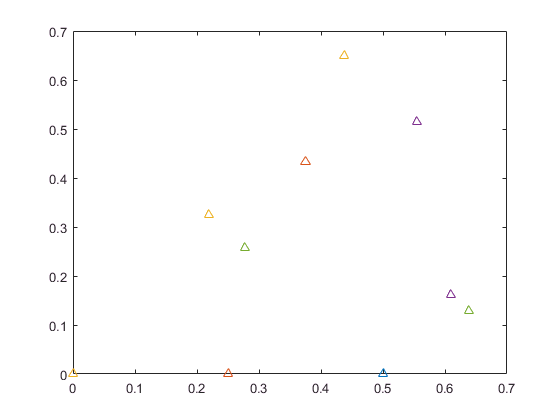

x=zeros(2,n);
y=x;
for i=2:n
    c=randi([1 3]);
    switch c
        case 1
            x(i)=.5*x(i-1);
            y(i)=.5*y(i-1);
        case 2
            x(i)=.5*x(i-1)+.25;
            y(i)=.5*y(i-1)+(sqrt(3)/4);
        case 3
            x(i)=.5*x(i-1)+.5;
            y(i)=.5*y(i-1);
    end
end
plot(x,y,'^')

## *Page 219, Problem 36*

Description

a3= input('Input a3')

a3 = 23

a2= input('Input a2')

a2 = 23

a1=input('Input a1')

a1 = 23

a0= input('Input a0')

a0 = 23

A=a2./a3;
B=a1./a3;
C=a0./a3;
Q=(3*B-A.^2)./9;
R=(9*A.*B-27.*C-2.*A.^3)./54;
D=Q.^3+R.^2

D = 0.1481

theta = acosd(R./sqrt(-Q.^3));
for n = 1:length(D)
    D(n) = roundn(D(n),-4);
    if D(n) > 0
        fprintf('The equation has complex roots')
    elseif D(n)==0
        x1=2*nthroot(R(n),3)-A(n)/3;
        x2=-nthroot(R(n),3)-A(n)/3;
        x3=-nthroot(R(n),3)-A(n)/3;
        fprintf('This equation has real roots which are %f, %f, and %f \n',x1,x2,x3);
    else 
        x1=2*sqrt(-Q(n))*cosd(theta(n)/3)-A(n)/3;
        x2=2*sqrt(-Q(n))*cosd(theta(n)/3+120)-A(n)/3;
        x3=2*sqrt(-Q(n))*cosd(theta(n)/3+240)-A(n)/3;
        fprintf('This equation has real roots which are %f, %f, and %f \n',x1,x2,x3);
    end
end

The equation has complex roots

# *Gilat 6th Edition, Chapter 7*

## *Page 248, Problem 1*

Description

% Part a
a = problem1(-2);
b = problem1(4);
fprintf(' y(-2) is %f and y(4) is %f.\n',a,b);

 y(-2) is 7.632791 and y(4) is 8.036691.


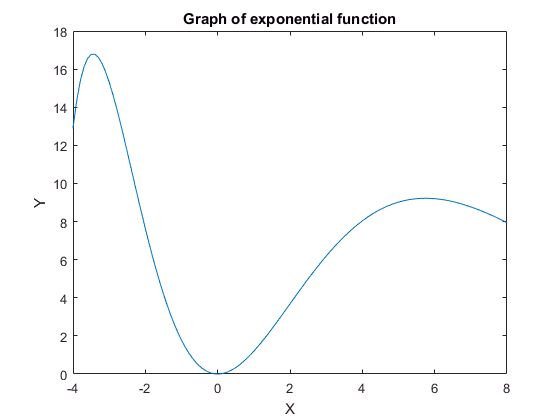

% Part b
xvals = -4:.1:8;
yvals = problem1(xvals);
figure
plot(xvals,yvals);
xlabel('X');
ylabel('Y');
title('Graph of exponential function');

## *Page 248, Problem 2*

Description

% Part a
theta = 0:.1:4*pi;
r = Prob2(theta);
fprintf('r(pi/6) is %f and r(5pi/6) is %f',Prob2(pi/6),Prob2(5*pi/6));

r(pi/6) is 0.724220 and r(5pi/6) is 2.102269

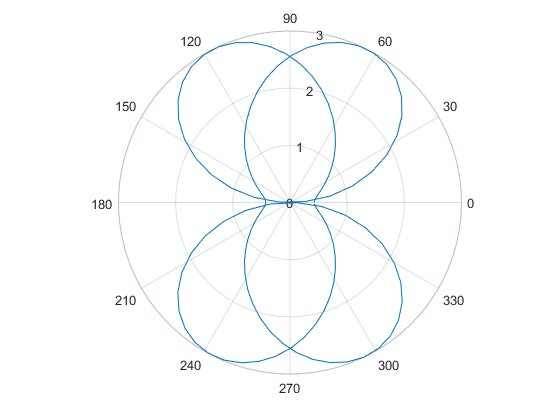

polarplot(theta,r);

## *Page 253, Problem 18*

Description

A = [7,1.2];
B = [.5,2.6];
C = [-2.4,-1.4];
xyr = Circle3Pts(A,B,C);
xyr = [round(xyr(1),2) round(xyr(2),2) round(xyr(3),2)]

xyr =     2.8700   -2.1700    5.3300


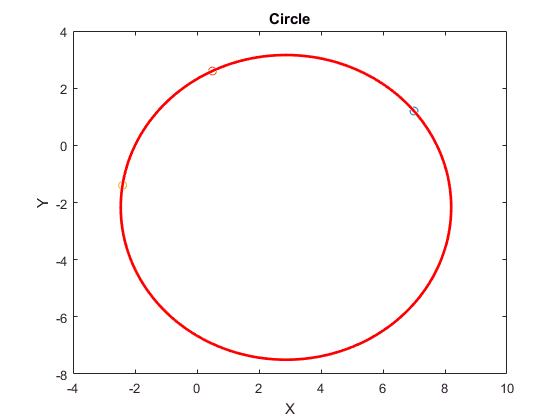

xpoints = [A(1) B(1) C(1)];
ypoints = [A(2) B(2) C(2)];
figure
plot(xpoints(1),ypoints(1),'o');
hold on
plot(xpoints(2),ypoints(2),'o');
hold on
plot(xpoints(3),ypoints(3),'o');
hold on
viscircles([xyr(1) xyr(2)],xyr(3));
xlabel('X');
ylabel('Y');
title('Circle');

## *Page 253, Problem 20*

Description

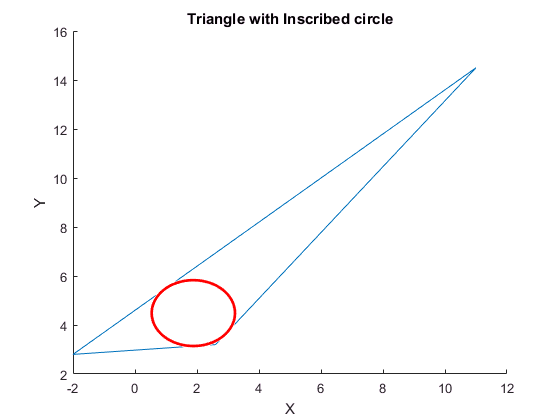

A = [2.6,3.2];
B = [11,14.5];
C = [-2,2.8];
figure
TriCirc(A,B,C)
xlabel('X');
ylabel('Y');
title('Triangle with Inscribed circle');

## *Page 256, Problem 31*

Description

dis=GreatCirDis(51.50853,-.12574,40.71427,-74.00597);
fprintf('The distance between New York and London is %.2f mi.',dis)

The distance between New York and London is 156885.52 mi.